load asdasd.mat

% data length, fs, f
L = 153600; fs = 614.4e6; 
% f = (1/4000)^(2n)
f = 34.35974e6;
f = 34359740;
dt = 1/fs;
T = 1/f;
dL = T/dt;
t = (1:L)'*dt;
singal_tone = 0;
rewrite = 1;

q = 0.5; i = 0.5;

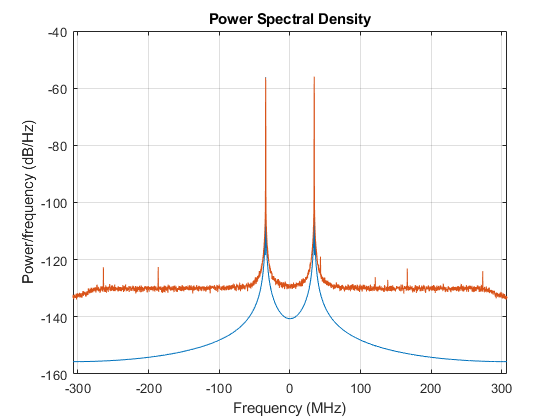

% plot the PSD
% figure;
% pwelch(yBB,2^12,[],[],614.4e6,'centered');
figure;
pwelch([x yBB],2^12,[],[],614.4e6,'centered');

%rms归一化
yBB = yBB/(rms(yBB));
x = x/(rms(x));
figure;
pwelch([x yBB],2^12,[],[],614.4e6,'centered');

% Interpolation 

tp = (1:10*L)'*(0.1*dt);
xp = interp1(t,x,tp,'spline');
yBBp=interp1(t,yBB,tp,'spline');

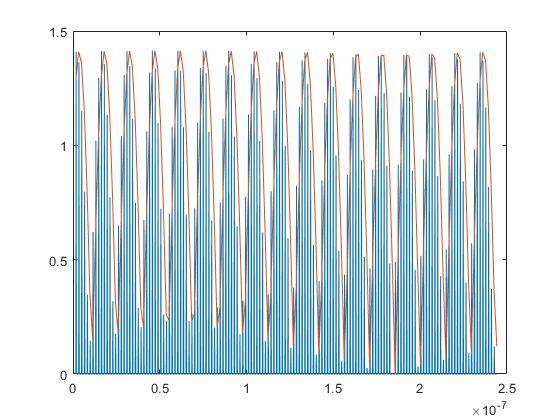


K = 10;
N = 1;
Npre = 1;
x_up=zeros(length(x)*K,1);
x_up(1:K:end)=x;
xp=x_up(1:Npre*N:end);


t1 = 1;
t2 = 150;
t3 = 10*t1;
t4 = 10*t2;

figure;
plot(tp(t3:t4),abs(xp(t3:t4)));
hold on
plot(t(t1:t2),abs(x(t1:t2)));

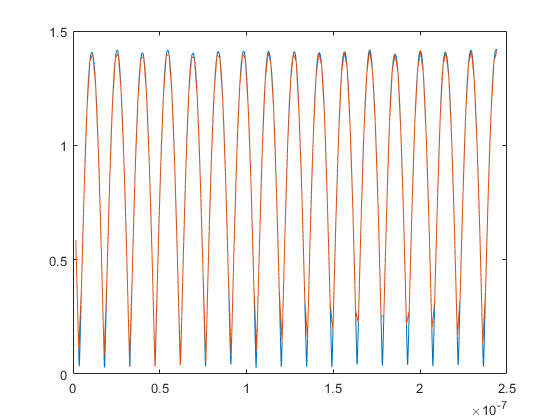

% plot(t(t1:t2),abs(yBB(t1:t2)));


figure;
plot(tp(t3:t4),abs(yBBp(t3:t4)));
hold on
plot(t(t1:t2),abs(yBB(t1:t2)));

% plot(tp(t3:t4),abs(xp(t3:t4)));


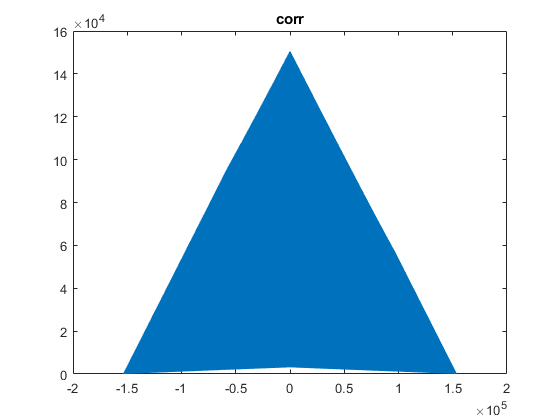

% align
t1 = 1300;
t2 = 1900;

%%%%%%%%%%%%%%%%%% 
[r,lags] = xcorr(yBB, x);


figure;
plot(lags,abs(r));
title("corr");

[val,idx]=max(abs(r));
offset=lags(idx)

offset = 4

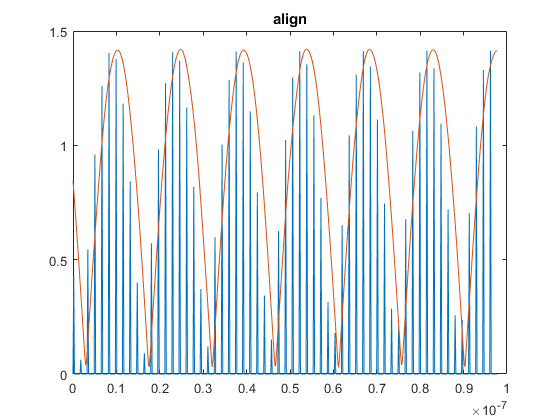

offset = 45;
figure;
plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
t3 = t1+offset;
t4 = t2+offset;
hold on
plot((tp(t3:t4)-tp(t3)),abs(yBBp(t3:t4)));
title("align");

% realign
error = 1e12;
index = 0;
temp = 0;
for k=(-20:20)
%     temp = sum((abs(yBBp(t3+k:t4+k))-abs(xp(t1:t2))).^2);
    temp = sum((abs(circshift(yBBp, k))-abs(xp)).^2);
%     disp(temp)
    if(temp < error)
        error = temp;
        index = k;
    end
end

offset1 = offset+index

offset1 = 65

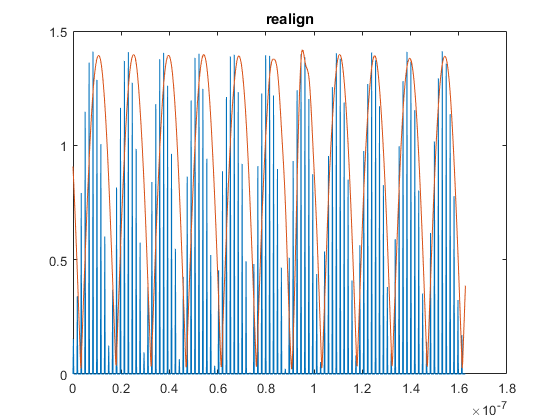


figure;
t1 = 961000;
t2 = t1+1000;
plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
t3 = t1;
t4 = t2;
yBBp1 = circshift(yBBp, 52);
hold on
plot((tp(t3:t4)-tp(t3)),abs(yBBp1(t3:t4)));
title("realign");

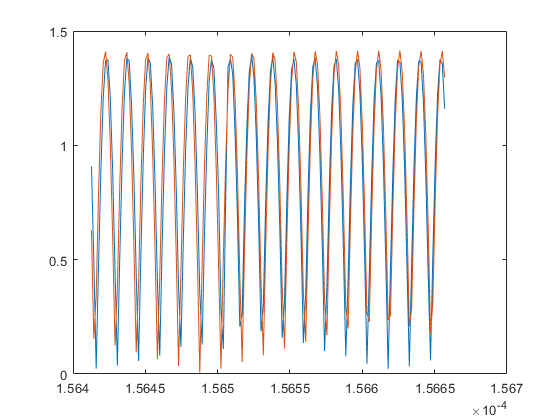

yasd = downsample(yBBp1, 10, 9);
yBB1 = circshift(yBB, round(-offset1/10));
t1 = 96100;
t2 = t1 + 150;
t3 = t1*10;
t4 = 10*t2;
figure;
plot(t(t1:t2),abs(yasd(t1:t2)))
hold on
plot(t(t1:t2),abs(x(t1:t2)))

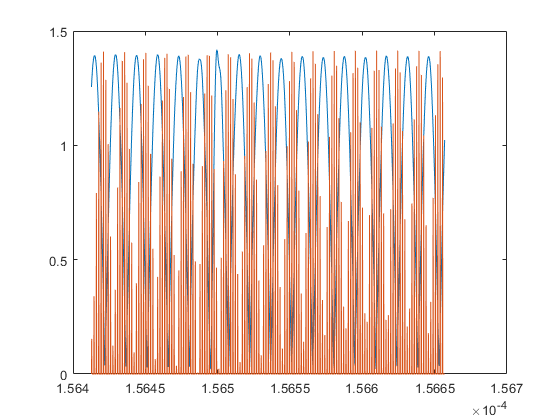


figure;
plot(tp(t3:t4),abs(yBBp(t3:t4)))
hold on
plot(tp(t3:t4),abs(xp(t3:t4)))

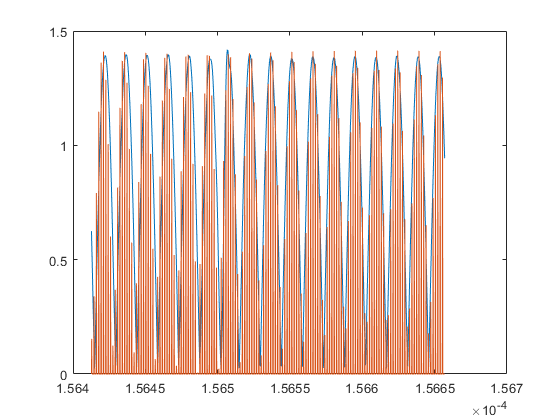


yBBp_delete = circshift(yBBp, 45);
figure;
plot(tp(t3:t4),abs(yBBp_delete(t3:t4)))
hold on
plot(tp(t3:t4),abs(xp(t3:t4)))

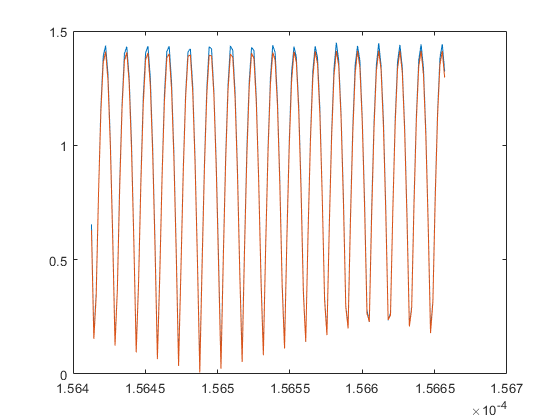


yBB_delete = circshift(yBB, 57520);
figure;
plot(t(t1:t2),abs(yBB_delete(t1:t2)))
hold on
plot(t(t1:t2),abs(x(t1:t2)))

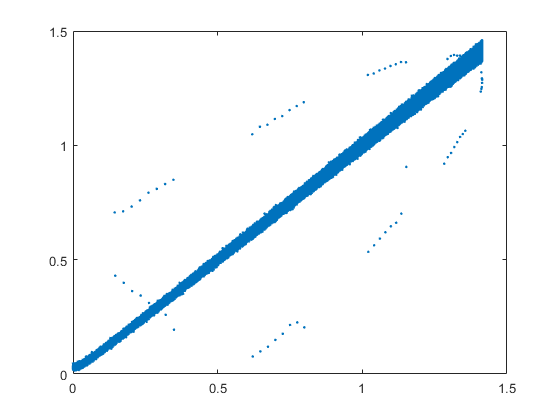


figure;
plot(abs(x), abs(yBB_delete),'.')

% error = 1e12;
% index = 0;
% temp = 0;
% for k=(0:L)
% %     temp = sum((abs(yBBp(t3+k:t4+k))-abs(xp(t1:t2))).^2);
%     temp = sum((abs(circshift(yBB, k))-abs(x)).^2);
% %     disp(temp)
%     if(temp < error)
%         error = temp;
%         index_delete = k;
%     end
% end
% disp(index_delete)

       57520



% [r,lags] = xcorr(abs(yBB), abs(x));

w = conv(abs(x),abs(yBB(end:-1:1)));

[val,idx]=max(abs(w))

val = 1.5088e+05

idx = 153596

idx = idx - 1*L

idx = -4

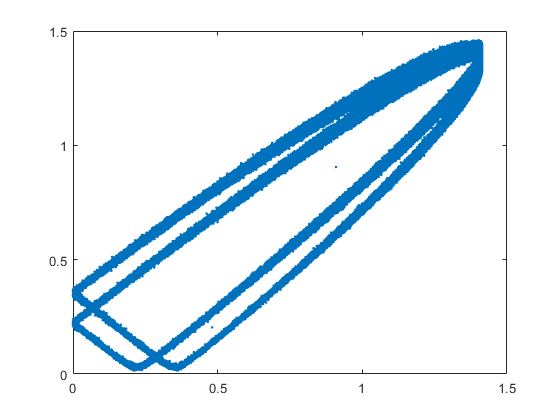

yBB_delete = circshift(yBB, idx);
figure;
plot(abs(x), abs(yBB_delete),'.')


resolution = 10;

xp1=dpd_resample(x,resolution,1,0.5,'ZEROS',L);
x111=dpd_FFTFilter(1,0,0.5,x,'LP',L);
yp1=dpd_resample(yBB_delete,resolution,1,0.5,'NORMAL',L);

Arrays have incompatible sizes for this operation.

Error in try1>dpd_FFTFilter (line 223)
    y=ifft(plantilla_fft.*tf);

Error in try1>dpd_resample (line 201)
        x_up=dpd_FFTFilter(1,0,(BWr2/K),x_up,'LP',L);   

Related documentation

function [y]=dpd_resample(x,Kx,Nx,BWr,type,L)

factors_Nx=factor(Nx);
K=Kx;
Npre=1;
N=Nx;

oversampling=floor(0.5/BWr);

switch type
   
    case 'NORMAL'
        
        for n=1:1:length(factors_Nx)
            buffer=factors_Nx(n);
            if ( (1/buffer)>2*BWr )
            Npre=factors_Nx(n);
            N=Nx/Npre;    
            end
        end
        
        for n=2:1:length(factors_Nx)
            buffer=factors_Nx(1)*factors_Nx(n);
            if ( ((1/buffer )>2*BWr) && (buffer>Npre) )
            Npre=buffer;
            N=Nx/Npre;    
            end
        end
                 
        if (Npre>1) 
           x=dpd_FFTFilter(1,0,BWr,x,'LP',L); 
        end
              
        x_predown=x(1:Npre:end);   
        BWr2=BWr*Npre;
        
        x_up=zeros(length(x_predown)*K,1);
        x_up(1:K:end)=x_predown;        
        x_up=dpd_FFTFilter(1,0,(BWr2/K),x_up,'LP',L);   
        x_up=x_up*K;
        
        y=x_up(1:N:end);
      
    case 'ZEROS'      
        x_up=zeros(length(x)*K,1);
        x_up(1:K:end)=x;
        y=x_up(1:Npre*N:end);
        
    otherwise
end

end

function [y]=dpd_FFTFilter(Fs,Fo,BWa,x,type,L)
    BW=ceil(L*BWa/Fs);
    plantilla_fft=zeros(L,1);    
    plantilla_fft(1:1:BW,1)=ones(BW,1);
    plantilla_fft(L-BW+2:1:L,1)=ones(BW-1,1);
    
    tf=fft(x); 
    y=ifft(plantilla_fft.*tf);
end